# enae432 hw11

vai srivastava

## problem 1

% givens
s  = zpk('s');
G = 6/(s+3)^2;

% display
G


G =
 
     6
  -------
  (s+3)^2
 
Continuous-time zero/pole/gain model.
Model Properties


### part a

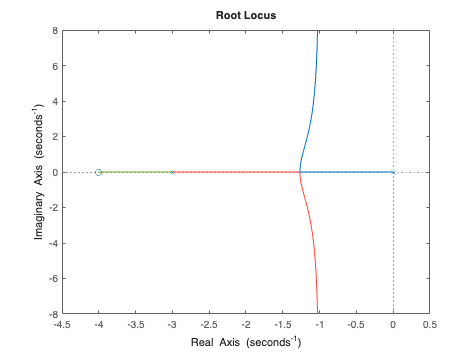

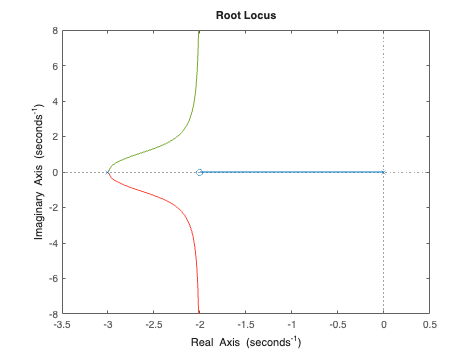

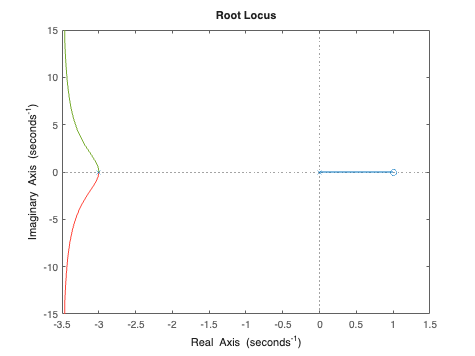

z = [-4, -2, 1];
for i=1:length(z)
        H0 = (s-z(i))/s;
        L0 = H0*G;
        fig = figure;
        rlocusplot(L0);
        saveas(fig, string('./images/s01a' + string(i) + '.png'));
end

### part d

zeta = 1/sqrt(2);
z = 3;
wn = 3/(2*zeta);
K  = wn^2/6;
Kp = K;
Ki = K*z;
H  = pid(Kp, Ki);
T  = feedback(G*H,1);

Kp, Ki, H, T

Kp = 0.7500

Ki = 2.2500


H =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.75, Ki = 2.25
 
Continuous-time PI controller in parallel form.
Model Properties

T =
 
        4.5 (s+3)
  ----------------------
  (s+3) (s^2 + 3s + 4.5)
 
Continuous-time zero/pole/gain model.


## problem 2

% givens
s = zpk('s');
G = 5*(s-1)/(s-6);

% display
G


G =
 
  5 (s-1)
  -------
   (s-6)
 
Continuous-time zero/pole/gain model.
Model Properties


### part b

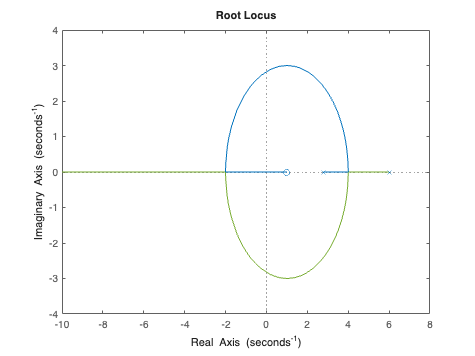

K = 64/25;
p = 14/5;
H = K/(s-p);
L = H*G;

fig = figure;
rlocusplot(L);
saveas(fig, './images/s02b.png');

### part c

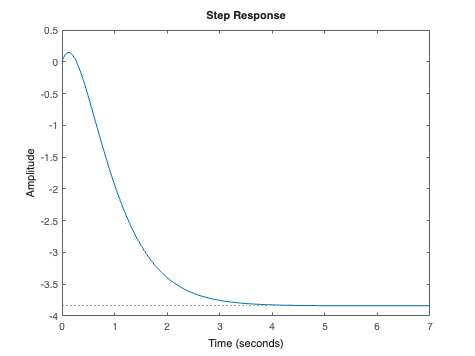

syms s_sym

R = feedback(H, G);
R_info = stepinfo(R);

fig = figure;
stepplot(R);
saveas(fig, './images/s02c.png');


[R_num, R_den] = tfdata(R);
RN = poly2sym(R_num, s_sym);
RD = poly2sym(R_den, s_sym);
R_sym = RN/RD;
U_sym = R_sym/s_sym;
ut_sym = ilaplace(U_sym)

$$ut\_sym = \frac{96\,{\mathrm{e}}^{-2\,t}}{25}+\frac{256\,t\,{\mathrm{e}}^{-2\,t}}{25}-\frac{96}{25}$$


% display
R, R_info, ut_sym


R =
 
  2.56 (s-6)
  ----------
   (s+2)^2
 
Continuous-time zero/pole/gain model.
Model Properties


R_info = struct with fields:
         RiseTime: 1.6515
    TransientTime: 3.0421
     SettlingTime: 3.0640
      SettlingMin: -3.8400
      SettlingMax: -3.4571
        Overshoot: 0
       Undershoot: 3.8196
             Peak: 3.8400
         PeakTime: 7.8058


$$ut\_sym = \frac{96\,{\mathrm{e}}^{-2\,t}}{25}+\frac{256\,t\,{\mathrm{e}}^{-2\,t}}{25}-\frac{96}{25}$$

### part d

% assuming sample time Ts = 1 second
Ts = 1/25;

% solution
[Ah, Bh, Ch, Dh] = ssdata(canon(H));
H_zoh.Ad = expm(Ah*Ts);
H_zoh.Bd = Ah \ (H_zoh.Ad-eye(size(Ah)))*Bh;
H_zoh.Cd = Ch;
H_zoh.Dd = Dh;

[Ad, Bd, Cd, Dd] = ssdata(c2d(H, Ts, 'tustin'));
H_tustin = struct('Ad', Ad, 'Bd', Bd, 'Cd', Cd, 'Dd', Dd);

% display tustin
H_zoh, H_tustin

H_zoh = struct with fields:
    Ad: 1.1185
    Bd: 0.0847
    Cd: 1.2800
    Dd: 0


H_tustin = struct with fields:
    Ad: 1.1186
    Bd: 0.3639
    Cd: 0.3158
    Dd: 0.0542


## problem 3

% givens
s = zpk('s');
H = 15*(3*s+1)^5/((s+1)^3*(s^2+2*s+10));
Ts = 1/25;

% display
H, Ts


H =
 
     3645 (s+0.3333)^5
  -----------------------
  (s+1)^3 (s^2 + 2s + 10)
 
Continuous-time zero/pole/gain model.
Model Properties


Ts = 0.0400

### part a

% solution
[Ah, Bh, Ch, Dh] = ssdata(canon(H));
Ad = expm(Ah*Ts);
Bd = Ah \ (Ad-eye(size(Ah)))*Bh;
Cd = Ch;
Dd = Dh;

% display
Ad, Bd, Cd, Dd

Ad =     0.9608   -0.0256   -0.0253         0         0
         0    0.9608   -0.0256         0         0
         0         0    0.9608         0         0
         0         0         0    0.9539    0.1150
         0         0         0   -0.1150    0.9539


Bd =     0.5968
    0.3022
    0.1012
    0.5486
    9.1941


Cd =   -46.5020  -46.5020  -46.5020  -24.1168  -46.6136


Dd = 3.6450e+03

### part b

% solution
[Ad, Bd, Cd, Dd] = ssdata(c2d(H, Ts, 'tustin'));

% display
Ad, Bd, Cd, Dd

Ad =     0.9608   -0.0260   -0.0260   -0.0076   -0.0409
         0    0.9608   -0.0260   -0.0076   -0.0409
         0         0    0.9608   -0.0076   -0.0409
         0         0         0    0.9540    1.0000
         0         0         0   -0.0132    0.9540


Bd =    10.3139
   10.3139
   10.3139
         0
   16.5140


Cd =    -8.5642   -8.5642   -8.5642   -2.5004  -13.4826


Dd = 3.4011e+03

## problem 4

% givens
s = zpk('s');
G = 2/(s^2*(s^2+3));

% display
G


G =
 
        2
  -------------
  s^2 (s^2 + 3)
 
Continuous-time zero/pole/gain model.
Model Properties


### part a

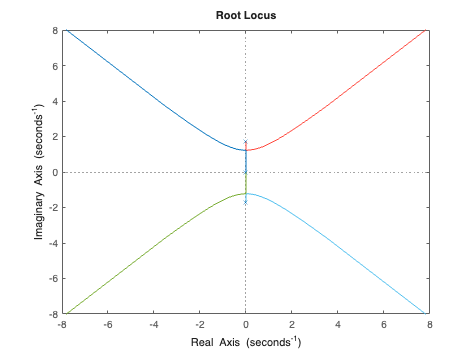

fig = figure;
rlocusplot(G);
saveas(fig, './images/s04a.png');

### part b

% givens
syms a2 a1 a0 b3 b2 b1 b0 s_sym
HD = s_sym^3+a2*s_sym^2+a1*s_sym+a0;
HN = b3*s_sym^3+b2*s_sym^2+b1*s_sym+b0;
desired = (s_sym-(-1+1j))*(s_sym-(-1-1j))*(s_sym+4)^5;

% solution
[G_num, G_den] = tfdata(G);
GN = poly2sym(G_num, s_sym);
GD = poly2sym(G_den, s_sym);

CL_den = expand(GD*HD+GN*HN);
coeffCL = coeffs(CL_den, s_sym, 'All');
coeffT  = coeffs(desired, s_sym, 'All');

eqs = coeffCL(2:end) == coeffT(2:end);
sol_sym = solve(eqs, [a2 a1 a0 b3 b2 b1 b0]);
sol = structfun(@double, sol_sym);

H_num = transpose(sol(4:7));
H_den = [1, transpose(sol(1:3))];

Hb = zpk(tf(H_num, H_den));
Lb = G*Hb;
Tb = feedback(Lb, 1);
poles_Tb = pole(Tb);
zeros_Tb = zero(Tb);

% display
Hb, Tb, poles_Tb, zeros_Tb


Hb =
 
  1141.5 (s+0.4939) (s^2 + 0.4093s + 1.816)
  -----------------------------------------
      (s+11.86) (s^2 + 10.14s + 78.74)
 
Continuous-time zero/pole/gain model.
Model Properties

Tb =
 
  2283 (s+0.4939) (s^2 + 0.4093s + 1.816)
  ---------------------------------------
          (s+4)^5 (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model

poles_Tb =   -4.0075 + 0.0000i
  -4.0023 + 0.0071i
  -4.0023 - 0.0071i
  -3.9939 + 0.0044i
  -3.9939 - 0.0044i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


zeros_Tb =   -0.2046 + 1.3321i
  -0.2046 - 1.3321i
  -0.4939 + 0.0000i


### part c

% givens
syms a3 a2 a1 a0 b3 b2 b1 b0 s_sym
HD = s_sym^4+a3*s_sym^3+a2*s_sym^2+a1*s_sym+a0;
HN = b3*s_sym^3+b2*s_sym^2+b1*s_sym+b0;
desired = (s_sym-(-1+1j))*(s_sym-(-1-1j))*(s_sym+4)^6;

% solution
[G_num, G_den] = tfdata(G);
GN = poly2sym(G_num, s_sym);
GD = poly2sym(G_den, s_sym);

CL_den = expand(GD*HD+GN*HN);
coeffCL = coeffs(CL_den, s_sym, 'All');
coeffT  = coeffs(desired, s_sym, 'All');

eqs = coeffCL(2:end) == coeffT(2:end);
sol_sym = solve(eqs, [a3 a2 a1 a0 b3 b2 b1 b0]);
sol = structfun(@double, sol_sym);

H_num = transpose(sol(5:8));
H_den = [1, transpose(sol(1:4))];

Hc = zpk(tf(H_num, H_den));
Lc = G*Hc;
Tc = feedback(Lc, 1);
poles_Tc = pole(Tc);
zeros_Tc = zero(Tc);

% display
Hc, Tc, poles_Tc, zeros_Tc


Hc =
 
     5597 (s+0.4116) (s^2 + 0.125s + 1.778)
  ---------------------------------------------
  (s^2 + 20.06s + 115.9) (s^2 + 5.939s + 51.91)
 
Continuous-time zero/pole/gain model.
Model Properties

Tc =
 
  11194 (s+0.4116) (s^2 + 0.125s + 1.778)
  ---------------------------------------
          (s+4)^6 (s^2 + 2s + 2)
 
Continuous-time zero/pole/gai

poles_Tc =   -4.0247 + 0.0000i
  -4.0123 + 0.0214i
  -4.0123 - 0.0214i
  -3.9877 + 0.0213i
  -3.9877 - 0.0213i
  -3.9753 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


zeros_Tc =   -0.0625 + 1.3320i
  -0.0625 - 1.3320i
  -0.4116 + 0.0000i


### part d

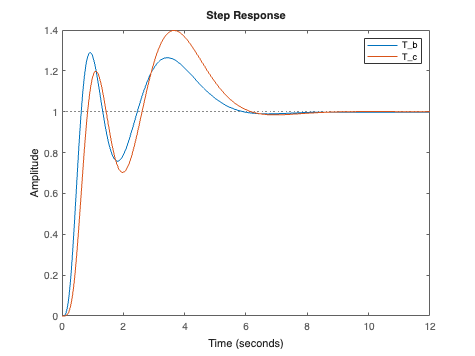

% solution
fig = figure;
hold on;
stepplot(Tb);
stepplot(Tc);
legend(["T_b" "T_c"]);
hold off;
saveas(fig, './images/s04d.png');


Tb_info = stepinfo(Tb);
Tc_info = stepinfo(Tc);

% display
Tb_info, Tc_info

Tb_info = struct with fields:
         RiseTime: 0.3510
    TransientTime: 5.5002
     SettlingTime: 5.5002
      SettlingMin: 0.7579
      SettlingMax: 1.2897
        Overshoot: 28.9658
       Undershoot: 0
             Peak: 1.2897
         PeakTime: 0.9193


Tc_info = struct with fields:
         RiseTime: 0.4342
    TransientTime: 5.8635
     SettlingTime: 5.8635
      SettlingMin: 0.7028
      SettlingMax: 1.3977
        Overshoot: 39.7657
       Undershoot: 0
             Peak: 1.3977
         PeakTime: 3.6616
